# Курсовая работа по теме "Анализ и моделрование временных рядов"

## Введение

**Временной ряд** — собранный в разные моменты времени статистический материал о значении каких-либо параметров исследуемого процесса. Каждая единица статистического материала называется измерением или отсчётом. Временной ряд существенно отличается от простой выборки данных, так как при анализе учитывается взаимосвязь измерений со временем, а не только статистические характеристики выборки.

Анализ временных рядов — совокупность математико-статистических методов анализа, предназначенных для выявления структуры временных рядов и для их прогнозирования. Выявление структуры временного ряда необходимо для того, чтобы построить математическую модель того явления, которое является источником анализируемого временного ряда. Прогноз будущих значений временного ряда используется для эффективного принятия решений.

Цели анализа временных рядов:

- определение природы ряда;

- прогнозирование (предсказание будущих значений временного ряда по настоящим и прошлым значениям).

Временные ряды, как правило, возникают в результате измерения некоторого показателя. Это могут быть как показатели (характеристики) технических систем, так и показатели природных, социальных, экономических и других систем (например, погодные данные). Типичным примером временного ряда можно назвать биржевой курс, при анализе которого пытаются определить основное направление развития (тенденцию или тренд).

В данной работе мы рассмотрим моделирование временного ряда на примере индексов цен на жилье, а также произведем анализ коррелированности двух рядов. При написании курсовой работы использован математический пакет MATLAB, который имеет многочисленный набор инструментов (в том числе эконометрических), необходимых для решения данной задачи.

## Задача 1: Моделирование временного ряда по моделе Бокса-Дженкинса

## Постановка задачи

Дан временной ряд идексов цен на жилье за период с 1995г. по 2014г. в формате HPI.xls. 

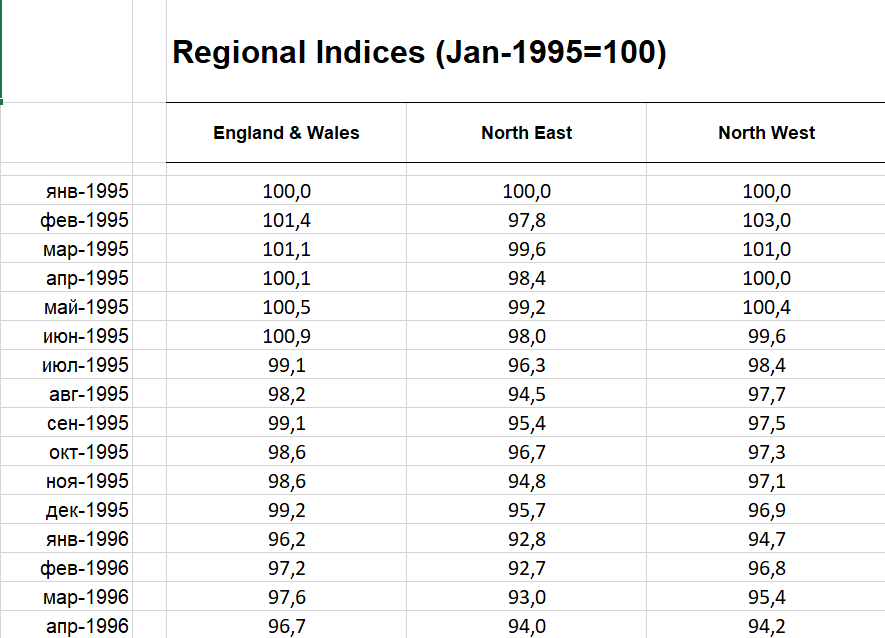Фрагмент исходных данных приведен на рис.1

Импортируя временной период и числовые показатели Англии и Уэльса, смоделировать поведение временного ряда, спрогнозировать его поведение на последующие 10 месяцев и провести тестирование методом Монте Карло.

## Описание методологии прогназирования

Временные ряды состоят из двух элементов:

- периода времени, за который или по состоянию на который приводятся числовые значения;

- числовых значений того или иного показателя, называемых уровнями ряда.

Классификация временных рядов:

- по количеству показателей (одномерные и многомерные временные ряды);

- по наличию пропущенных значений (полные и неполные временные ряды);

- в зависимости от наличия основной тенденции (стационарные и нестационарные ряды).

Стационарный временной ряд - это ряд, безусловное совместное распределение которого не изменяется при сдвиге во времени.

Наиболее распространенной причиной нарушения стационарности является тенденция в среднем значении, которое может быть обусловлено либо наличием единого корня, либо детерминированного тренда. В первом случае (DS-ряды) случайные скачки имеют постоянные эффекты, и процесс не является возвратным к среднему. В последнем случае (TS-ряды) скачки имеют только временные эффекты, после которых переменная стремится к детерминистически развивающемуся (непостоянному) среднему значению.

**Стационарный относительно тренда ряд** (*TS-ряд, trend stationary*) — временной ряд, для которого существует некоторая детерминированная функция, такая что их разность является стационарным процессом.

$X_t\ -\ TSseries \Leftrightarrow \exists f(t) : X_t-f(t) - стационарный\ ряд$.

Важным видом нестационарного ряда, который не включает трендоподобное поведение, является **циклостационарный ряд**, который является стохастическим процессом, который циклически изменяется со временем.

**Интегрированный временной ряд** — нестационарный временной ряд, разности некоторого порядка от которого являются стационарным временным рядом. Такие ряды также называют *разностно-стационарными (DS-рядами, Difference Stationary).*

$X_t \sim I(k) \Leftrightarrow \Delta^k X_t \sim I(0), \ где\ I(0) - стационарный\ ряд$.

Понятие интегрированного временного ряда тесно связано с единичными корнями в авторегрессионных моделях. Наличие единичных корней в характеристическом полиноме авторегрессионной составляющей модели временного ряда означает интегрированность временного ряда. Причем количество единичных корней совпадает с порядком интегрированности.

**ARIMA** (*autoregressive integrated moving average*) — модель авторегрессионного интегрированного скользящего среднего, являющаяся расширением моделей ARMA для нестационарных временных рядов. Модель $ARIMA(p,d,q)$ означает, что разности временного ряда порядка $d$ подчиняются модели $ARMA(p,q)$.

Формальное определение $ARIMA(p,d,q)$модели:

$a(L)(1-L)^d X_t = c+b(L)\varepsilon_t, \ где\  \Theta(L)=\sum_{i=0}^{N}\theta_i L_i -\ лаговый\  многочлен$.

Формальное определение $ARMA(p,q)$модели:

$a(L) X_t = c+b(L)\varepsilon_t, \ где\  \Theta(L)=\sum_{i=0}^{N}\theta_i L_i -\ лаговый\  многочлен$.

Замечание: **лаговый оператор** ($L$)— оператор смещения, позволяющий получить значения элементов временного ряда на основании ряда предыдущих значений.

$L^k X_t= X_{t-k}$.

**Этапы моделирования временного ряда в методологии Бокса-Дженкенса:**

- **Предобработка данных**

В первую очередь оценивается стационарность ряда. Для интегрированных временных рядов применяется подход ARIMA. Различными тестами выявляются наличие единичных корней и порядок интегрированности временного ряда (обычно ограничиваются первым или вторым порядком). Далее при необходимости (если порядок интегрированности больше нуля) ряд преобразуется взятием разности соответствующего порядка и уже для преобразованной модели строится некоторая ARMA-модель.

В случае TS-рядов для того, чтобы сделать ряд стационарным, нужно удалить тренды, сезонные компоненты и бизнес циклы. О наличие сезонной составляющей можно судить по наличию периодически повторяющихся пиков автокорреляционной функции. Для удаления этой состовляющей можно воспользоваться цифровой обработкой сигнала. Для вычленения циклов можно использовать фильтр Ходрика–Прескотта. Он разделяет временной ряд на трендовые и циклические компоненты. Математически фильтр Ходрика-Прескотта записывается как задача минимизации следующей функции потерь:

$\sum_{t=1}^T {\left(y_t -s_t \right)}^2 +\lambda \sum_{t=2}^{T-1} {\left(\left(s_{t+1} -s_t \right)-\left(s_t -s_{t-1} \right)\right)}^2 \to \mathrm{min}$.

Рекомендуемые параметры сглаживания: 14400 (месяц), 1600 (квартал), 100 (год).

Первая сумма минимизирует разницу между временным рядом и его трендовой компонентой (которая является его циклической составляющей). Вторая сумма минимизирует разницу второго порядка тренда (что аналогично минимизации второй производной тренда).

Тесты на стационарность:

1.Тест Квятковского–Филлипса–Шмидта–Шина (KPSS);

Проверяет гипотезу стационарности относительно тренда против альтернативной гипотезы о наличии единичного корня. Статистический критерий: $\frac{\sum\limits_{t=1}^N S^2_t}{s^2N^2}$, где $S_t = e_1+e_2+\cdots+e_t$ (невязки МНК),$N$- размер выбоки, $s^2$ - оценка Ньюи-Уэста долгосрочной дисперсии (количество лагов автоковариации, которые необходимо включить в оценку Ньюи-Уэста предлагается считать равным$\sqrt N$).

2.Расширенный тест Дики–Фуллера (ADF).

Проверяет гипотезу наличия единичного корня против альтернативной о его отсутствии. Критические значения *DF*-статистики берутся из специальной таблицы Дики — Фуллера. Если значение статистики лежит левее критического значения (критические значения — отрицательные) при данном уровне значимости, то нулевая гипотеза о единичном корне отклоняется и процесс признается стационарным (в смысле данного теста). В противном случае гипотеза не отвергается и процесс может содержать единичные корни, то есть быть нестационарным (интегрированным) временным рядом

- **Выбор модели**

На основании автокорреляционной (ACF) и частной автокорреляционной функции (PACF) определятся порядок членов авторегрессии и скользящего среднего.

**Автокорреляция** — статистическая взаимосвязь между последовательностями величин одного ряда, взятыми со сдвигом.

**Автокорреляционная функция** показывает зависимость автокорреляции от величины сдвига во времени. **Частная** же **автокорреляционная функция** показывает прямое влияние$y_t$ на $y_{t-k}$ (с вычетом влияния $y_{t-1},\dots,y_{t-k+1}$).

Оптимальная модель выбирается на основе информационного критерия Акаике.

**Информационный критерий** — применяемая в статистике мера относительного качества статистических моделей, учитывающая степень «подгонки» модели под данные с корректировкой на используемое количество оцениваемых параметров. То есть критерии основаны на неком компромиссе между точностью и сложностью модели. Критерии различаются тем, как они обеспечивают этот баланс. Чем меньше значение критерия, тем лучше модель.

Информационный критерий Акаике рассчитывается по формуле $AIC = 2k-2l$, где $l$ - значение логарифмической функции правдоподобия построенной модели, а $k$ - количество использованных (оцененных) параметров.

- **Оценка модели**

На данном этапе производится оценка остаточного распределения, проверка на гетероскедастичность и окончательная оценка параметров комбинированной ARIMA/GARCH модели.

**Гетероскедастичность **— неоднородность наблюдений, выражающаяся в неодинаковой (непостоянной) дисперсии случайной ошибки модели. Гетероскедастичность противоположна *гомоскедастичности*, означающей однородность наблюдений, то есть постоянство дисперсии случайных ошибок модели.

- **Симуляция и прогноз**

## Решение поставленной задачи

### Предобработка данных

Импортируем данные из таблицы HPI.xls

T = readtable('HPI.xls','Sheet','Indices', ...
    'Range','B4:D233', 'ReadVariableNames',false);
dates = T.Var1;
HPI = T.Var3;

Выведем график

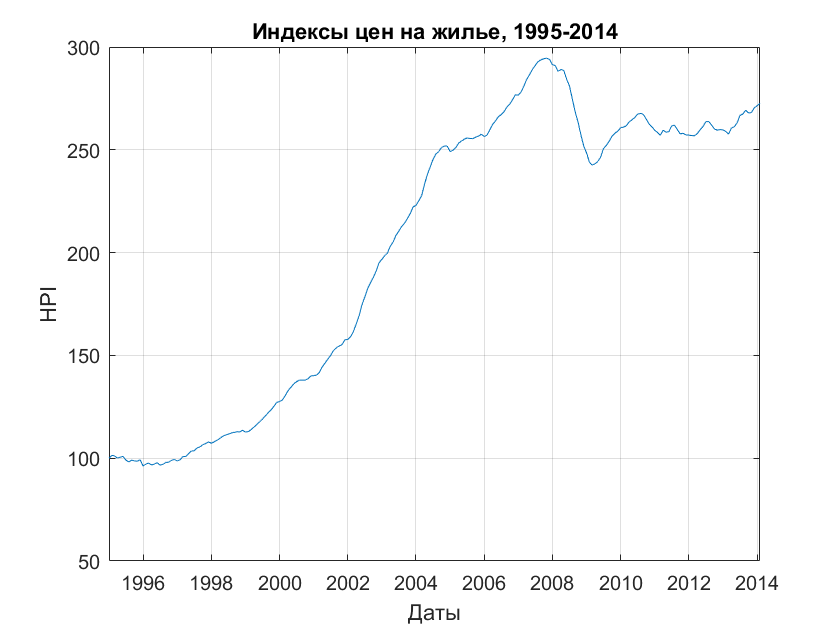

plot(dates, HPI)
title('Индексы цен на жилье, 1995-2014')
xlabel('Даты')
ylabel('HPI')
grid on

Проанализируем основные характеристики статистических данных - среднее значение и среднеквадратичное отклонение (далее СКО)

n_fragments = rem(numel(HPI), 12); % Количество дней в последнем неполном месяце
years = year(dates(1:end-n_fragments)); % Года с повторениями
yrsHPI = HPI(1:end-n_fragments); 
[meanHPIByYear, stdHPIByYear] =...
    grpstats(yrsHPI, years, {@mean, @std}); % Среднее значение и ско HPI по годам
yrs = unique(years); % Года

Визуализация соотношения среднего и СКО

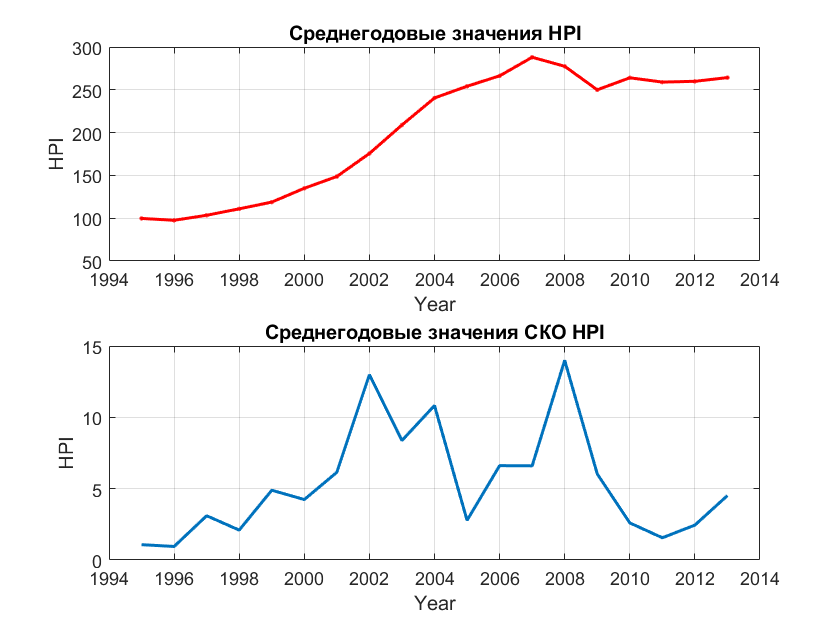

figure('Name', 'Характеристики статистических данных', 'NumberTitle', 'off');
subplot(2,1,1)
plot(yrs, meanHPIByYear, 'r.-', 'LineWidth', 1.5)
title('Среднегодовые значения HPI')
xlabel('Year')
ylabel('HPI')
grid on
subplot(2,1,2)
plot(yrs, stdHPIByYear, 'LineWidth', 1.5)
title('Среднегодовые значения СКО HPI')
xlabel('Year')
ylabel('HPI')
grid on

Приходим к выводу, что данные нестационарны.

#### Выявление экпоненциального тренда

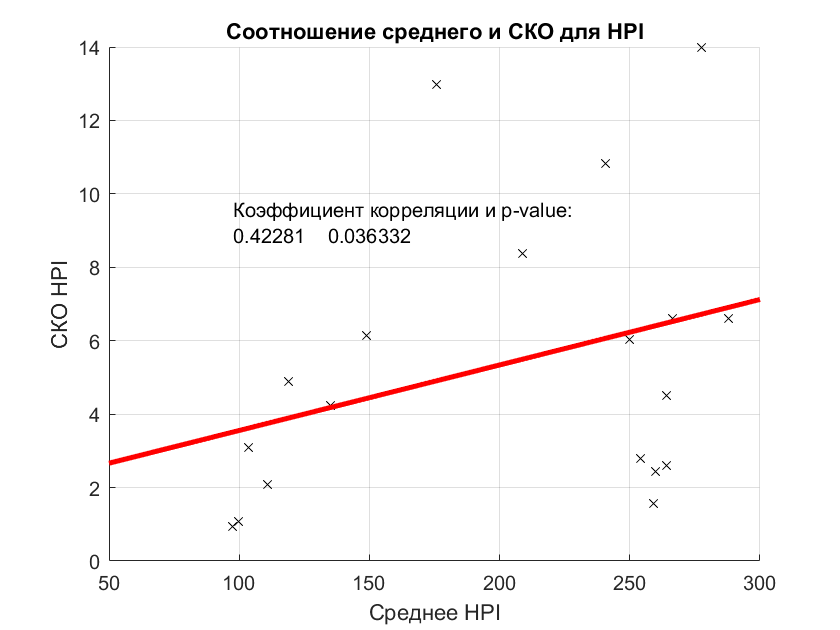

figure
scatter(meanHPIByYear,stdHPIByYear,'kx')
xlabel('Среднее HPI')
ylabel('СКО HPI')
title('Соотношение среднего и СКО для HPI')
grid on
l = lsline;
set(l, 'Color', 'r', 'LineWidth', 2.5)
[c, p] = corr(meanHPIByYear, stdHPIByYear, 'type', 'Spearman', 'tail', 'right');
display_text = char('Коэффициент корреляции и p-value:', num2str([c, p]));
text( min(meanHPIByYear), mean(stdHPIByYear)+std(stdHPIByYear), display_text)

Удаление экспоненциального тренда из HPI серии:

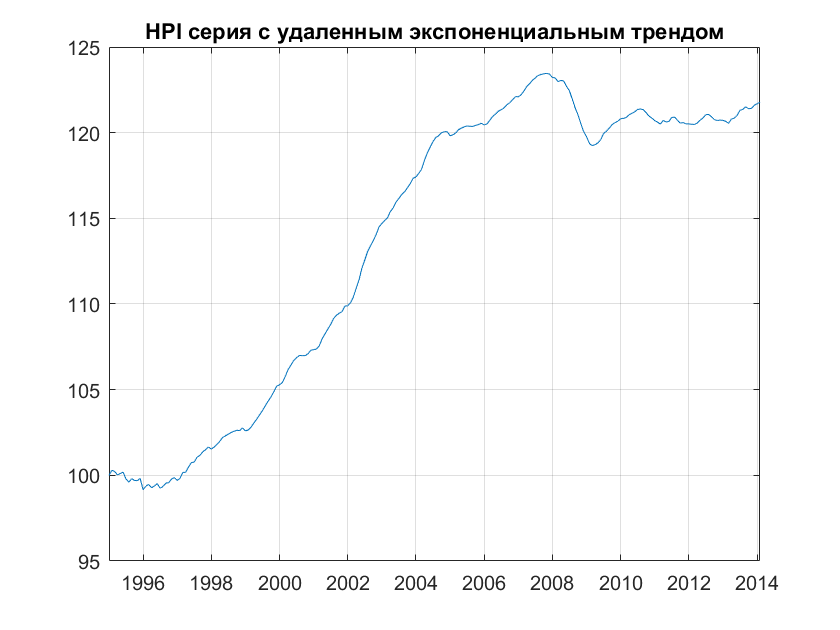

HPI_log = log(HPI);
plot(dates, HPI_log*100/HPI_log(1))
title('HPI серия с удаленным экспоненциальным трендом')
grid on

#### Взятие разности

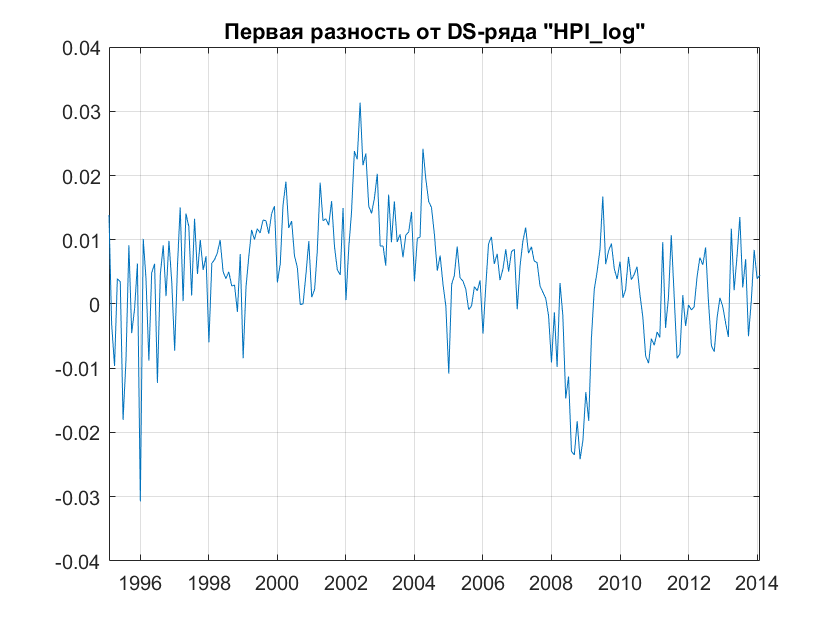

first_diff = LagOp([1, -1], 'Lags', [0,1]); % Задаем полином лагового оператора
dHPI = filter(first_diff, HPI_log); % Применяем лаговый оператор
lagdates = dates(2:end); % Временная переменная после взятия разности

plot(lagdates, dHPI)
title('Первая разность от DS-ряда "HPI\_log"')
grid on

#### Тест на стационарность

n_test_lags = floor(sqrt(numel(dHPI)));
h = kpsstest(dHPI, 'lags', n_test_lags, 'trend', true);
disp('Проведен тест Квятковского-Филлипса-Шмидта-Шина')

Проведен тест Квятковского-Филлипса-Шмидта-Шина


disp(['Решением об отклонении нуль гипотезы: ',num2str(h)])

Решением об отклонении нуль гипотезы: 1


if h==1
    disp('Ряд нестационарен')
elseif h==0
    disp('Ряд стационарен')
end

Ряд нестационарен


#### Идентификация полиномиального тренда

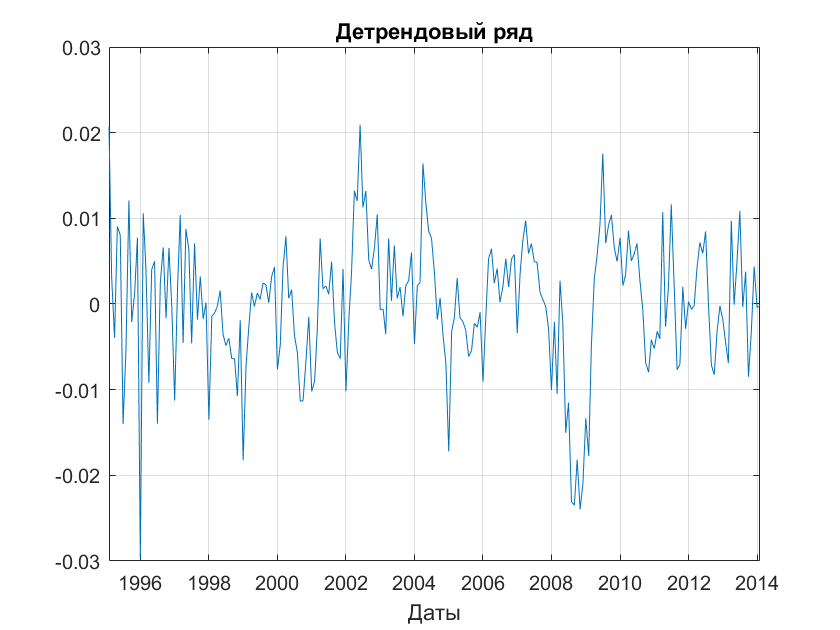

dn = days(lagdates-lagdates(1)); % Отностельое время в днях
[trend_fit, ~, date_stats] = polyfit(dn, dHPI, 3); % Подбор кубического полинома
trend_val = polyval(trend_fit, dn, [], date_stats); % Значения полиномиального тренда
detrend = dHPI - trend_val; % Детрендовый ряд

plot(lagdates,detrend)
title('Детрендовый ряд')
xlabel('Даты')
grid on

#### Тест на стационарность 2

n_test_lags = floor(sqrt(numel(detrend)));
h = kpsstest(detrend, 'lags', n_test_lags, 'trend', false);
disp('Проведен тест Квятковского-Филлипса-Шмидта-Шина')

Проведен тест Квятковского-Филлипса-Шмидта-Шина


disp(['Решением об отклонении нуль гипотезы: ',num2str(h)])

Решением об отклонении нуль гипотезы: 0


if h==1
    disp('Ряд нестационарен')
elseif h==0
    disp('Ряд стационарен')
end

Ряд стационарен


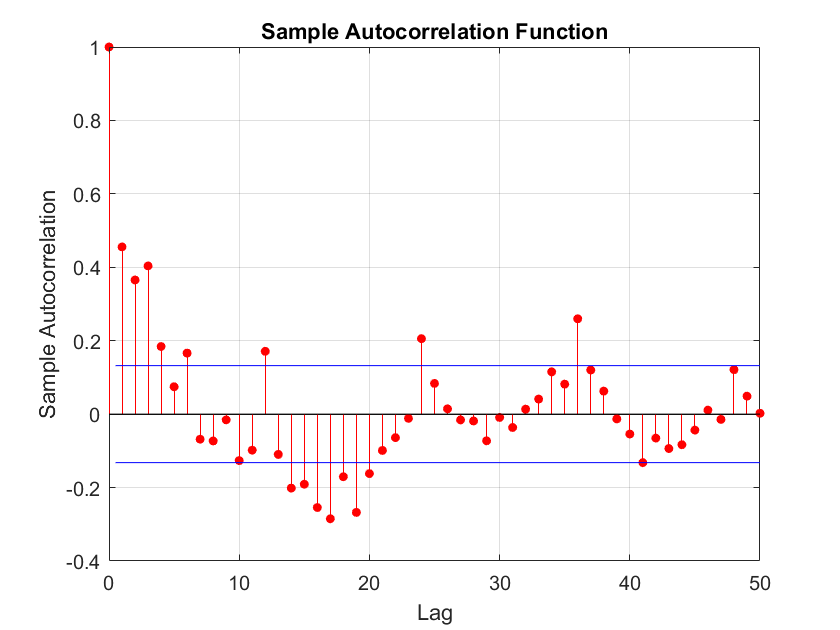

statHPI = detrend; % Стационарный временной ряд
autocorr(detrend,50)

На основании данных выборочной коррелограммы заключаем, что присутствует сезонная компонента. Включим ее в будущую модель.

### Выбор модели

#### Сравнение ACF и PACF

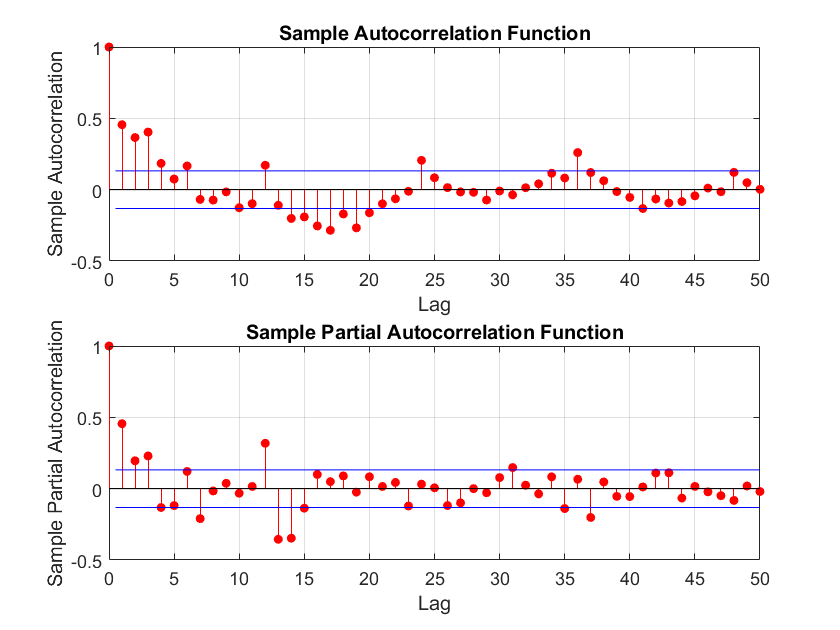

figure
nLag = 50;
subplot(2,1,1)
autocorr(statHPI, nLag)
subplot(2,1,2)
parcorr(statHPI, nLag)

Исходя из данных ACF и PACF коэффициенты p и q для модели ARMA(p,q) вычленить не удалось.

#### Идентификация моделей кандидатов

$$ARIMA(i, 0, j)$$, где $$i = 1\dots5, j = 1\dots5;$

Mdl = cell(1,1);
for i =1:5
    for j = 1:5
        hpi_model = arima('D',0,...
            'Seasonality',12,...
            'ARLags', 1:i,...
            'MALags', 1:j,...
            'SARLags', 12, ...
            'Constant', 0);
        hpi_model = estimate(hpi_model,statHPI);
        Mdl{i,j} = summarize(hpi_model);
    end
end

 
    ARIMA(1,0,1) Model Seasonally Integrated with Seasonal AR(12) (Gaussian Distribution):
 
                Value    StandardError    TStatistic    PValue
                _____    _____________    __________    ______

    Constant     0.00        0.00             NaN         NaN 
    AR{1}        0.89        0.03           25.92        0.00 
    SAR{12}     -0.40        0.05           -8.35        0.00 
    MA{1}       -0.40        0.06           -6.26        0.00 
    Variance     0.00        0.00           12.45        0.00 

 
    ARIMA(1,0,2) Model Seasonally Integrated with Seasonal AR(12) (Gaussian Distribution):
 
                Value    StandardError    TStatistic    PValue
               

Сравнение информационного критерия Акаике

z = zeros(size(Mdl));
for i = 1:size(Mdl,1)
    for j = 1:size(Mdl,2)
        z(i,j) = Mdl{i,j}.AIC;
    end
end
figure
heatmap(z) % Карта значений AIC

ans =   HeatmapChart with properties:

        XData: {5×1 cell}
        YData: {5×1 cell}
    ColorData: [5×5 double]

  Show all properties


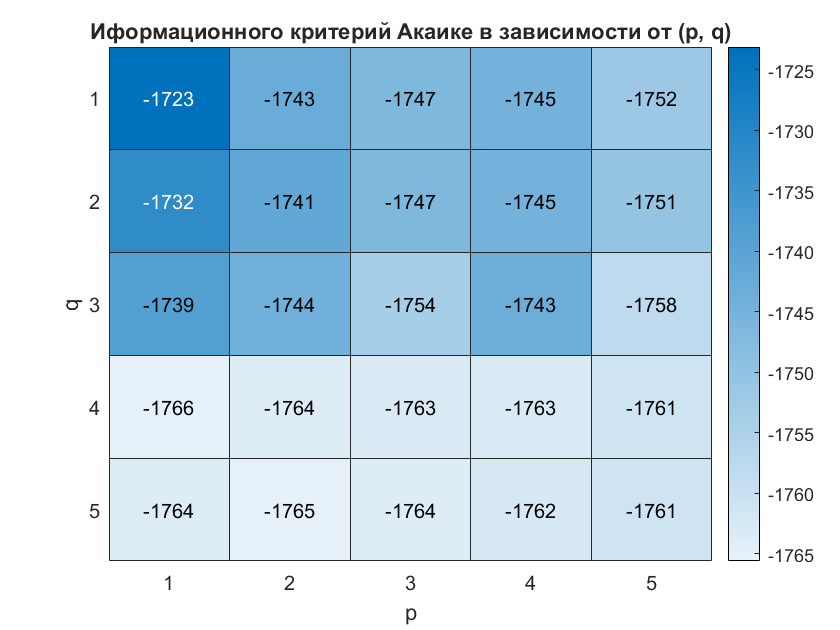

title('Иформационного критерий Акаике в зависимости от (p, q)')
xlabel('p')
ylabel('q')

Наименьшее значение AIC показывает модель $$ARIMA(1, 0, 4)$$.

#### Создание ARIMA модели и оценка ее коэффициентов

chosenModel = arima('D',0,...
                'Seasonality',12,...
                'ARLags', 1,...
                'MALags', 1:3,...
                'SARLags', 12, ...
                'Constant', 0);
[chosenModel, Q1] = estimate(chosenModel,statHPI); % Оценка коэффициентов модели

 
    ARIMA(1,0,3) Model Seasonally Integrated with Seasonal AR(12) (Gaussian Distribution):
 
                Value    StandardError    TStatistic    PValue
                _____    _____________    __________    ______

    Constant     0.00        0.00             NaN         NaN 
    AR{1}        0.83        0.05           17.33        0.00 
    SAR{12}     -0.35        0.05           -7.01        0.00 
    MA{1}       -0.50        0.07           -7.04        0.00 
    MA{2}        0.19        0.07            2.79        0.01 
    MA{3}        0.20        0.07            2.76        0.01 
    Variance     0.00        0.00           12.19        0.00 



### Оценка адекватности модели

#### Анализ остаточного распределения

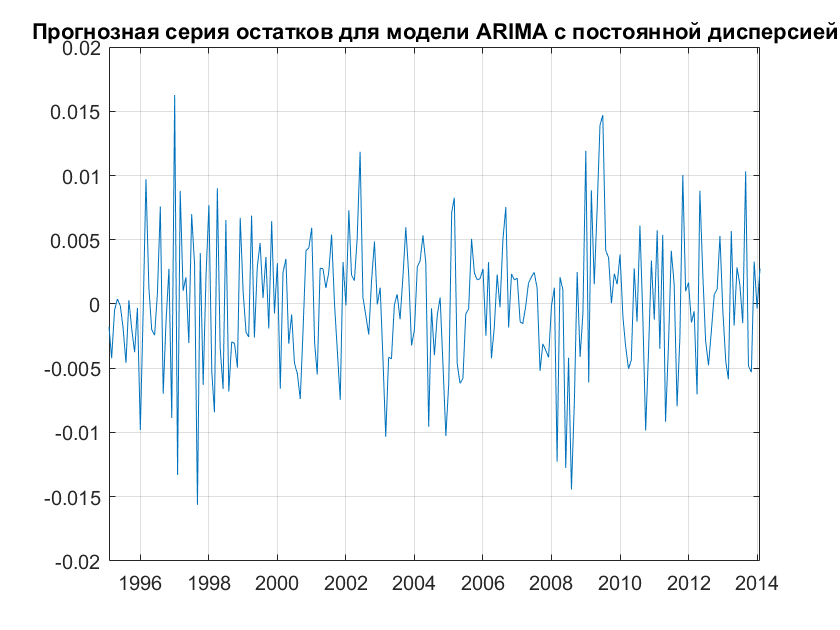

res = infer(chosenModel, statHPI); % Остатки в модели

figure
plot(lagdates, res)
title('Прогнозная серия остатков для модели ARIMA с постоянной дисперсией')
grid on

Расчет среднего

disp(['Среднее значение остатков: ',num2str(mean(res))])

Среднее значение остатков: -5.8269e-05


Визуализация распределения остатков

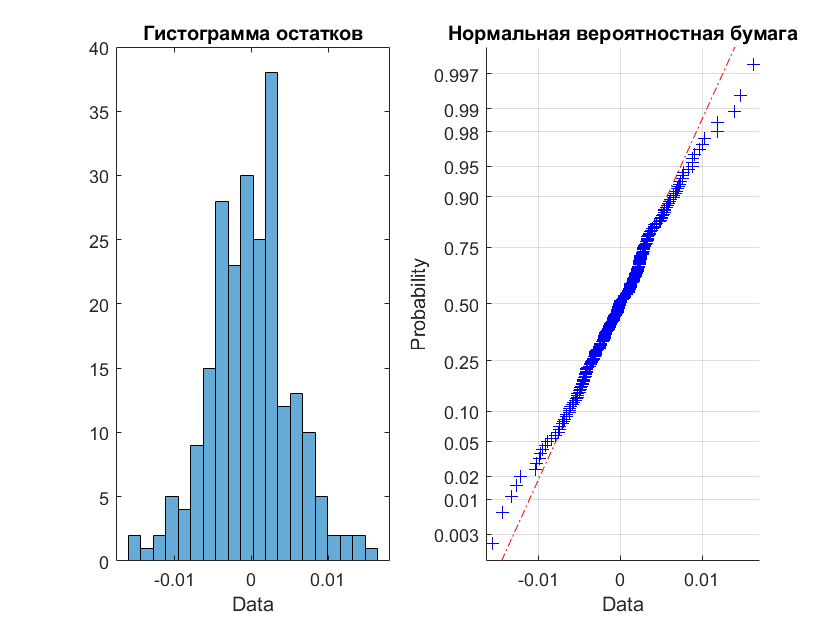

figure
subplot(1, 2, 1)
histogram(res, 20)
xlabel('Data')
title('Гистограмма остатков')
subplot(1, 2, 2)
normplot(res)
title('Нормальная вероятностная бумага')

Отображение результатов формального тестирования

T = table(~jbtest(res), ~adtest(res), ~lillietest(res), ...
    'VariableNames', {'JB_NORMAL', 'AD_NORMAL', 'LILLIE_NORMAL'});
disp('Проверка нормальной гипотезы на остатках:')

Проверка нормальной гипотезы на остатках:


disp(T)

    JB_NORMAL    AD_NORMAL    LILLIE_NORMAL
    _________    _________    _____________

      true         true           true     



#### Анализ автокорреляции и дисперсии остатков

Количество оцениваемых коэффициентов

SAR_coeffs = cell2mat(chosenModel.SAR);
n_est_coeffs = numel(chosenModel.AR)+numel(chosenModel.MA)+nnz(SAR_coeffs);

Тест гипотезы на автокорреляцию

(Нуль гипотеза: отсутствие автокорреляции)

Box_lags = min(20, numel(res)-1);
h = lbqtest(res, 'lags', Box_lags, 'dof', Box_lags-n_est_coeffs);
disp(['Результат Q-теста Льюнга-Бокса: ',num2str(h)])

Результат Q-теста Льюнга-Бокса: 1


Исследование условной гетероскедастичности

h = lbqtest(res.^2, 'lags', 1);
disp(['Q-тест Льюнга-Бокса на автокорреляцию квадратов ошибок: ',num2str(h)])

Q-тест Льюнга-Бокса на автокорреляцию квадратов ошибок: 1


Выполнение ARCH теста Энгла на условную гетероскедастичности

(Нулевая гипотеза: нет arch эффектов)

h = archtest(res, 'lags', 1:5);
disp('ARCH тест Энгла на условную гетероскедантичность:')

ARCH тест Энгла на условную гетероскедантичность:


disp(h)

   1   1   1   1   1



#### Модель условной гетероскедастичности

Инициализация кандидатов моделей

var_model{1} = garch(1, 1);
var_model{2} = garch(0, 1);
var_model{3} = garch(1, 2);

Оценка каждой модели и вывод статистики

for k = numel(var_model):-1:1
    [var_model{k}, cov_mat{k}, logLik(k)] = estimate(var_model{k}, res);
end

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                Value    StandardError    TStatistic    PValue
                _____    _____________    __________    ______

    Constant    0.00         0.00            0.93        0.35 
    GARCH{1}    0.90         0.03           26.29        0.00 
    ARCH{1}     0.05         0.06            0.90        0.37 

 
    GARCH(0,1) Conditional Variance Model (Gaussian Distribution):
 
                Value    StandardError    TStatistic    PValue
                _____    _____________    __________    ______

    Constant    0.00         0.00            9.54        0.00 
    

for k = numel(var_model):-1:1
    var_model_info{k} = summarize(var_model{k});
end

Сравнение моделей с использованием информационного критерия

nEstParams = [var_model_info{1}.NumEstimatedParameters, ...
              var_model_info{2}.NumEstimatedParameters];
[aic, bic] = aicbic(logLik(1:2), nEstParams, numel(res));

Отчеты.

[~, posAIC] = min(aic);
[~, posBIC] = min(bic);
disp(['AIC предлагает модель #:', num2str(posAIC)])

AIC предлагает модель #:2


disp(['BIC предлагает модель #:', num2str(posBIC)])

BIC предлагает модель #:2


#### Оценка комбинированной ARIMA/GARCH модели

overallModel = arima('D', 0, 'Seasonality', 12, ... 
                   'ARLags', 1, ...
                   'MALags', 1:3, ...
                   'SARLags', 12, ... 
                   'Constant', 0, ... 
                   'Variance', garch(0, 1));

Подбор параметров модели

warning('off', 'MATLAB:rankDeficientMatrix')
[overallModel, Q] = estimate(overallModel, statHPI);

 
    ARIMA(1,0,3) Model Seasonally Integrated with Seasonal AR(12) (Gaussian Distribution):
 
                Value    StandardError    TStatistic    PValue
                _____    _____________    __________    ______

    Constant     0.00        0.00             NaN         NaN 
    AR{1}        0.80        0.05           16.35        0.00 
    SAR{12}     -0.30        0.06           -5.24        0.00 
    MA{1}       -0.45        0.09           -5.11        0.00 
    MA{2}        0.16        0.07            2.22        0.03 
    MA{3}        0.22        0.07            2.91        0.00 

 
 
    GARCH(0,1) Conditional Variance Model (Gaussian Distribution):
 
                Value    StandardError    TSta

warning('on', 'MATLAB:rankDeficientMatrix')

Диагностика

summarize(overallModel)

 
   ARIMA(1,0,3) Model Seasonally Integrated with Seasonal AR(12) (Gaussian Distribution)
 
    Effective Sample Size: 229
    Number of Estimated Parameters: 7
    LogLikelihood: 882.763
    AIC: -1751.53
    BIC: -1727.49
 
                Value    StandardError    TStatistic    PValue
                _____    _____________    __________    ______

    Constant     0.00        0.00             NaN         NaN 
    AR{1}        0.80        0.05           16.35        0.00 
    SAR{12}     -0.30        0.06           -5.24        0.00 
    MA{1}       -0.45        0.09           -5.11        0.00 
    MA{2}        0.16        0.07            2.22        0.03 
    MA{3}        0.22        0.07            2.91        0.00 

 
 
   

### Прогноз и симуляция

#### Прогноз

Создание прогноза

n_forecat_period = 10; % Количество временных шагов для прогноза
[stat_forecast, forecast_mse, forecast_var] = ...
    forecast(overallModel, n_forecat_period, 'Y0', statHPI);

Вычисление прогнозных дат

forecast_dates = lagdates(end) + calmonths(1:n_forecat_period).';
new_dates = [lagdates(end); forecast_dates]; % Даты

Создание пользовательской визуализации

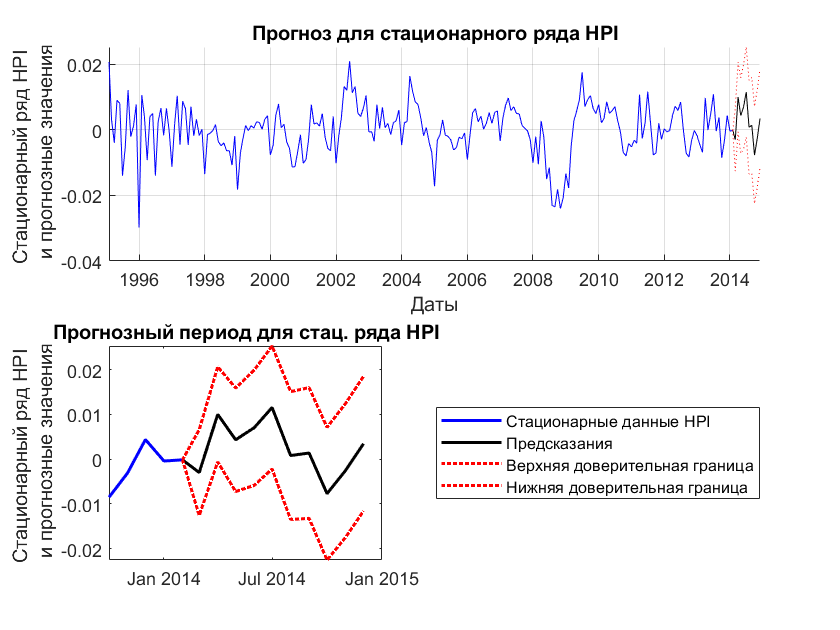

% Значения прогнозов и доверительные интервалы
forecast_vals = [statHPI(end); stat_forecast];
upperConfBound = forecast_vals + 1.96*sqrt([0; forecast_mse]);
lowerConfBound = forecast_vals - 1.96*sqrt([0; forecast_mse]);

figure
subplot(2, 1, 1)
hold on
plot(lagdates, statHPI, 'b')
plot(new_dates, forecast_vals, 'k')
plot(new_dates, upperConfBound, 'r', 'LineStyle', ':')
plot(new_dates, lowerConfBound, 'r', 'LineStyle', ':')
title('Прогноз для стационарного ряда HPI')
xlabel('Даты')
ylabel(sprintf('Стационарный ряд HPI \n и прогнозные значения'))
grid on
hold off
subplot(2, 1, 2)
plot(lagdates(end-4:end), statHPI(end-4:end), 'b', 'LineWidth', 1.5)
hold on
plot(new_dates, forecast_vals, 'k', 'LineWidth',1.5)
plot(new_dates, upperConfBound, 'r', 'LineWidth', 1.5, 'LineStyle', ':')
plot(new_dates, lowerConfBound, 'r', 'LineWidth', 1.5, 'LineStyle', ':')
title('Прогнозный период для стац. ряда HPI')
ylabel(sprintf('Стационарный ряд HPI \n и прогнозные значения'))
legend({'Стационарные данные HPI','Предсказания','Верхняя доверительная граница',...
    'Нижняя доверительная граница'},'Location','eastoutside')
hold off

#### Моделирование Монте Карло

Расчет траекторий модели Монте-Карло для стационарных данных HPI

n_forecat_period = 10;
statHPI_sim = simulate(overallModel, n_forecat_period, 'NumPaths', 1000, 'Y0', statHPI);                          

Извлекаем среднюю траекторию и ее доверительные интервалы

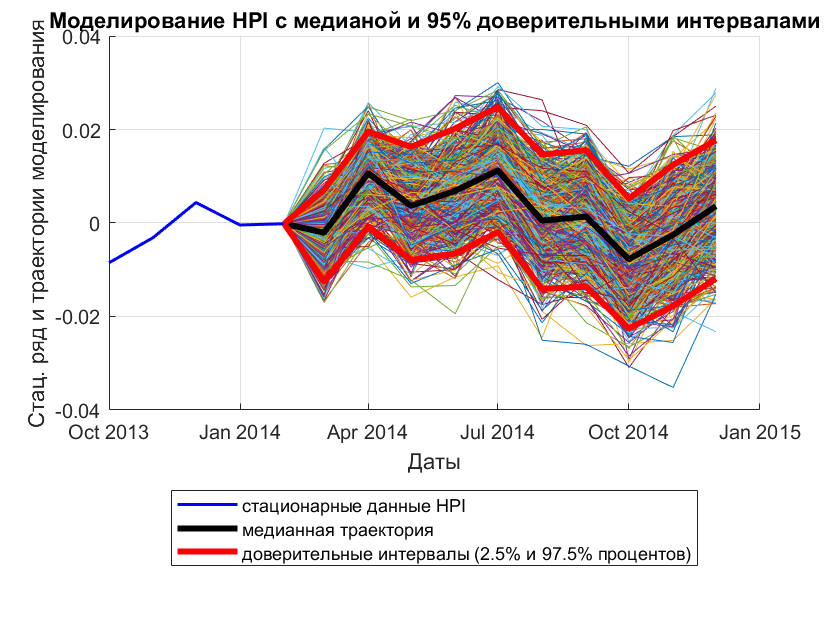

required_prctiles = [2.5, 50, 97.5]; % Требуемые вероятности
n_prctiles = numel(required_prctiles);
m = (n_prctiles-1)/2;
statHPI_proj = prctile(statHPI_sim, required_prctiles, 2); % Процентили для прогноза

figure
hold on
plot(lagdates(end-4:end), statHPI(end-4:end), 'b', 'LineWidth', 1.5)
plot(new_dates, [repmat(statHPI(end), 1, size(statHPI_sim, 2)); statHPI_sim],...
    'HandleVisibility', 'off')
plot(new_dates, [statHPI(end); statHPI_proj(:, m+1)], 'k', 'LineWidth', 3)
plot(new_dates, [repmat(statHPI(end), 1, size(statHPI_proj, 2)-1);...
    statHPI_proj(:, [1:m, m+2:end])], 'r', 'LineWidth', 3, 'LineStyle','-')
title('Моделирование HPI с медианой и 95% доверительными интервалами')
xlabel('Даты')
ylabel(sprintf('Стац. ряд и траектории моделирования'))
legend({'стационарные данные HPI', 'медианная траектория',...
    'доверительные интервалы (2.5% и 97.5% процентов)'}, 'Location', 'southoutside')
grid on
hold off

#### Обратное преобразование

allDates = [lagdates; forecast_dates];
X = [repmat(statHPI, 1, 3); lowerConfBound(2:end), stat_forecast, upperConfBound(2:end)];
trend_to_add = polyval(trend_fit, days(allDates-dates(2)),...
    [], date_stats); % Генерация полиномиального тренда
X = X + repmat(trend_to_add, 1, 3); % Возвращаем полиномиальный тренд
X = cumsum([repmat(HPI_log(1), 1, 3); X]);%Коммулятивная сумма (обратна к взятию разности)
X = exp(X); % Возвращаем экспоненциальный тренд

Визуализация

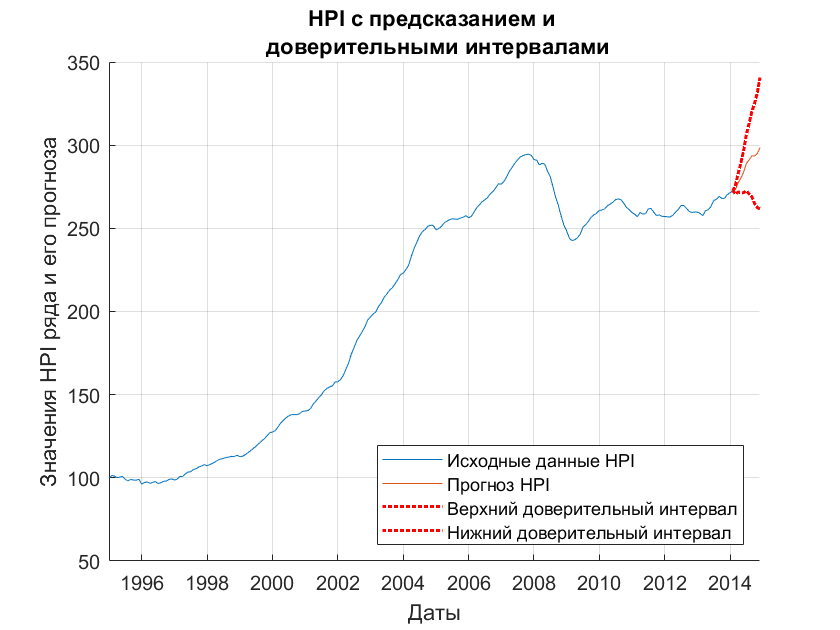

HPI = X(1:end-n_forecat_period, 2);
lower_HPI = X(end-n_forecat_period:end, 1);
forecast_HPI = X(end-n_forecat_period:end, 2);
upper_HPI = X(end-n_forecat_period:end, 3);

figure
hold on
plot(dates, HPI)
plot(new_dates, forecast_HPI)
plot(new_dates, upper_HPI, 'r', 'LineWidth',1.5, 'LineStyle',':')
plot(new_dates, lower_HPI, 'r', 'LineWidth',1.5, 'LineStyle',':')
title(sprintf('HPI с предсказанием и \n доверительными интервалами'))
xlabel('Даты')
ylabel('Значения HPI ряда и его прогноза')
legend({'Исходные данные HPI', 'Прогноз HPI', 'Верхний доверительный интервал',...
    'Нижний доверительный интервал'}, 'Location', 'southeast')
grid on
hold off

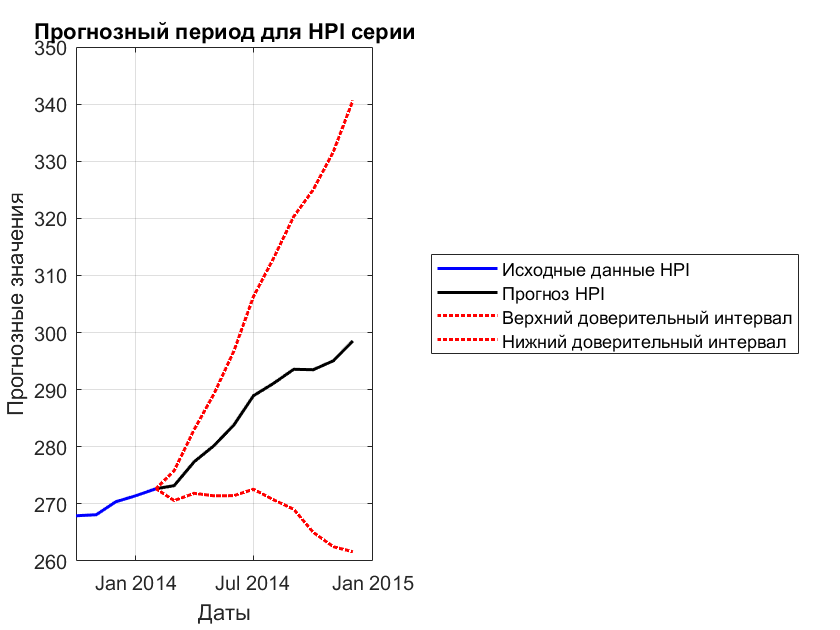

figure
plot(dates(end-4:end), HPI(end-4:end), 'b', 'LineWidth', 1.5)
hold on
plot(new_dates, forecast_HPI, 'k', 'LineWidth', 1.5)
plot(new_dates, upper_HPI, 'r', 'LineWidth', 1.5, 'LineStyle',':')
plot(new_dates, lower_HPI, 'r', 'LineWidth', 1.5, 'LineStyle',':')
title('Прогнозный период для HPI серии')
xlabel('Даты')
ylabel('Прогнозные значения')
legend({'Исходные данные HPI', 'Прогноз HPI', 'Верхний доверительный интервал',...
    'Нижний доверительный интервал'}, 'Location', 'eastoutside')
grid on
hold off

## Задача 2: Взаимная корреляция временных рядов

## Постановка задачи

Приведены данные по заболеваемости и выздоровлению от COVID-19 в Москве в период 12.03.20-29.11.20 в формате time_series_COVID.xlsx. Вычислить среднее время выздоровления.

## Решение поставленной задачи

#### Импортирование

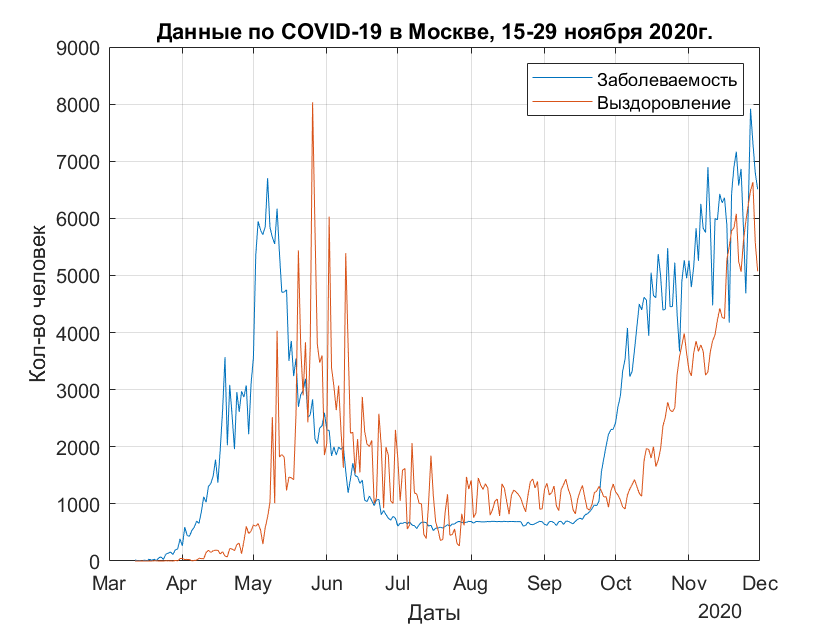

T2 = readtable('time_series_COVID.xlsx','Sheet','Chart data', ...
    'Range','A2:C265', 'ReadVariableNames',false);
dates = T2.Var1; % Даты
infected = T2.Var2; % Заболевшие
recovered = T2.Var3; % Выздоровевшие
plot(dates, infected, dates, recovered)
title('Данные по COVID-19 в Москве, 15-29 ноября 2020г.')
xlabel('Даты')
ylabel('Кол-во человек')
legend('Заболеваемость','Выздоровление', 'Location','northeast')
grid on

#### Рассчет взаимной корреляции

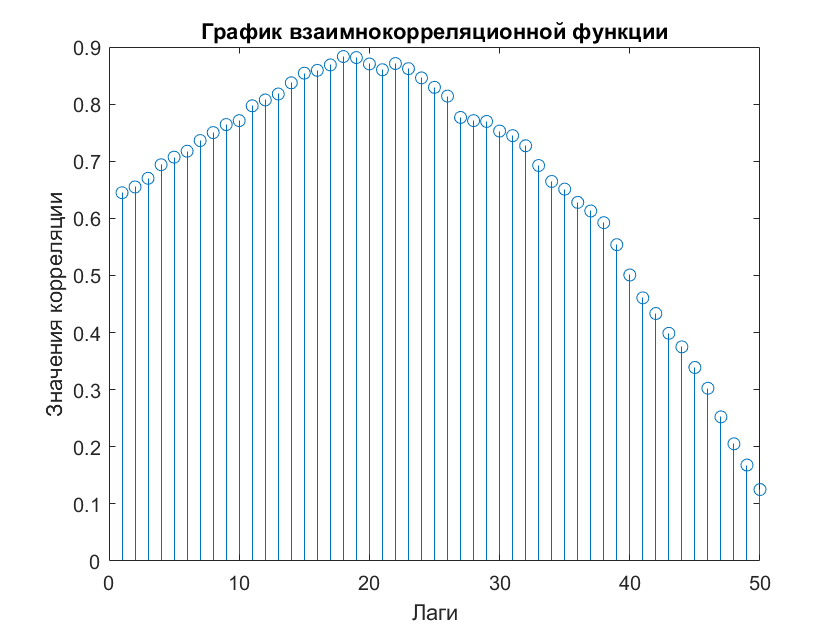

rho = zeros(50,1); % Инициализация массива для корреляции
lags = 1:50; % Сдвиги
for k = lags
   rho(k) = corr(infected(1:end-k),recovered(k+1:end));
end
stem(lags,rho)
title('График взаимнокорреляционной функции')
xlabel('Лаги')
ylabel('Значения корреляции')

[maxrho, recovtime] = max(rho);
disp("Среднее время выздоровления составляет " + recovtime +" дней.")

Среднее время выздоровления составляет 18 дней.
